clc
clear
close all

%% ********* Banderas de Configuración ************
rest = true;      % true: Con restricciones en actuadores
nominal = true;   % true: Caso nominal sin errores de modelo
simulink = true; % false: Simular en Matlab usando el Toolbox

%% Incertidumbres del Modelo (Para robustez)
deltak = 0.0; % Incertidumbre en ganancia
deltaL = 0;   % Incertidumbre en retardo

if nominal == true
    e1 = 0.0; e2 = 0.0; e3 = 0.0; 
else
    e1 = 0.2; e2 = 0.2; e3 = 0.3; 
end

%% Definición de la Planta (Proceso Real)
Psr = [tf(4.05+2.11*e1,[50 1]) tf(1.77+0.39*e2,[60 1]) tf(5.88+0.59*e3,[50 1]);...
       tf(5.39+3.29*e1,[50 1]) tf(5.72+0.57*e2,[60 1]) tf(6.9+0.89*e3,[40 1]);...
       tf(4.38+3.11*e1,[33 1]) tf(4.42+0.73*e2,[44 1]) tf(7.2+1.33*e3,[19 1])];

Lr = [27 28 27; 18 14 15; 20 22 0] + 0; 
Psr.iodelay = Lr; 

%% Etiquetas para las Gráficas
ylab{1}='Composición Superior (Top)';
ylab{2}='Composición Lateral (Side)';
ylab{3}='Temperatura Reflujo Inferior';
ulab{1}='Caudal de Extracción Superior';
ulab{2}='Caudal de Extracción Lateral';
ulab{3}='Calor del Reflujo Inferior';

%% Definición del Modelo Matemático Nominal
Ps = [tf(4.05,[50 1]) tf(1.77,[60 1]) tf(5.88,[50 1]);...
      tf(5.39,[50 1]) tf(5.72,[60 1]) tf(6.9,[40 1]);...
      tf(4.38,[33 1]) tf(4.42,[44 1]) tf(7.2,[19 1])];

Ls = [27 28 27; 18 14 15; 20 22 0];
Ps.iodelay = Ls;

% Periodo de muestreo e iteraciones
Ts = 4.0;
nit = 400;

Ps = Ps * (1+deltak);
Ps.iodelay = Ls + deltaL;

% Discretización del sistema (Zero-Order Hold)
Pz = c2d(Ps, Ts, 'zoh');
[my, ny] = size(Pz);

%% Escalamiento de Matrices (Condicionamiento Mínimo)
Km = dcgain(Pz); 
[L, R, S] = CondMin(Km); 


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Converged 


Found algebraic loop that contains: 
MPC_Shell3x3/MPC Controller /MPC/optimizer/optimizer
MPC_Shell3x3/MPC Controller /MPC/umin_scale1
MPC_Shell3x3/Subsystem1/Matrix Multiply1
MPC_Shell3x3/Shell 3x3/Reshape
MPC_Shell3x3/Shell 3x3/Internal/CT/State-Space
MPC_Shell3x3/Shell 3x3/Internal/CT/State-Space


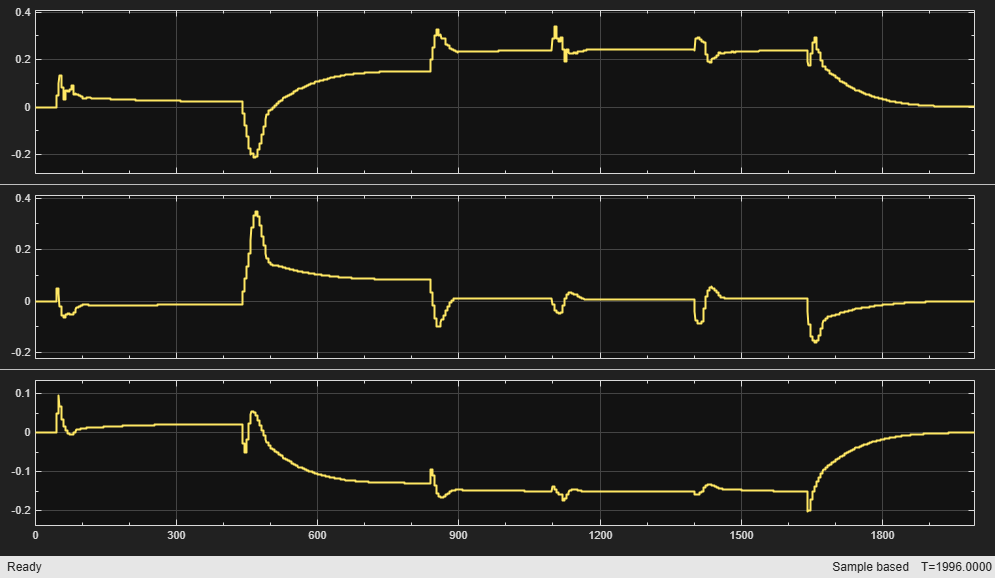

Pze = L * Pz * R; 

%% Creación del Controlador MPC
sysd = setmpcsignals(Pze, 'MV', [1; 2; 3]);
mpcverbosity off;
mpc_toolbox = mpc(sysd, Ts);

% Puntos Nominales
mpc_toolbox.Model.Nominal.U = L * [0; 0; 0];
mpc_toolbox.Model.Nominal.Y = R \ [0; 0; 0];

%% Restricciones Físicas de Actuadores
if rest == true
    InUmx = [0.05 0.05 0.05]; 
    InUmn = -InUmx;           
    Umx = [0.5 0.5 0.5];      
    Umn = -[1 1 1];           
    Ymx = inf * ones(1, 3);   
    Ymn = -inf * ones(1, 3);  
else
    InUmx = inf * ones(ny, 1);
    InUmn = -InUmx;
    Umx = inf * ones(ny, 1);
    Umn = -Umx;
    Ymx = inf * ones(my, 1);
    Ymn = -Ymx;
end

% Asignación de restricciones al objeto MPC
for i = 1:ny
    mpc_toolbox.MV(i).Min = R(i,i) \ Umn(i);
    mpc_toolbox.MV(i).Max = R(i,i) \ Umx(i);
    mpc_toolbox.MV(i).RateMin = R(i,i) \ InUmn(i);
    mpc_toolbox.MV(i).RateMax = R(i,i) \ InUmx(i);
end
for i = 1:my
    mpc_toolbox.OV(i).Min = L(i,i) * Ymn(i);
    mpc_toolbox.OV(i).Max = L(i,i) * Ymx(i);
end

%% Parámetros de Sintonía (Horizontes y Pesos)
N = 24; 
Nu = [6 2 2];
delta = [0.0107  0.0040  0.0008];
lambda = [0.0001 0.0006  0.0015];

mpc_toolbox.PredictionHorizon = max(N);
mpc_toolbox.ControlHorizon = max(Nu);
mpc_toolbox.Weights.OV = delta;
mpc_toolbox.Weights.MVRate = lambda;
mpc_toolbox.Weights.ECR = 10000;

options = mpcsimopt(mpc_toolbox);
options.RefLookAhead = 'off';
options.MDLookAhead = 'off';
options.Constraints = 'on';
options.OpenLoop = 'off';

%% Creación de Setpoints (Referencias)
Xsp = zeros(3, nit); % PREASIGNACIÓN CORRECTA
inK = 10;
Xsp(1, inK:80) = 0.2; Xsp(1, 80:200) = 0;   Xsp(1, 200:300) = 0.1; Xsp(1, 300:400) = 0.0;
Xsp(2, inK:80) = 0.2; Xsp(2, 80:200) = 0.4; Xsp(2, 200:300) = 0.3; Xsp(2, 300:400) = 0.0;
Xsp(3, inK:80) = 0.2; Xsp(3, 80:200) = 0.1; Xsp(3, 200:300) = 0.0; Xsp(3, 300:400) = 0.0;

% Escalar y transponer señales (reemplaza row2col)
r = (L * Xsp)'; 
t = 0:Ts:(nit-1)*Ts;            

%% Ejecución de la Simulación
if simulink == false
    [y, t, u, xp] = sim(mpc_toolbox, nit, r, [], options);
    
    % Retornar variables a su escala original
    y = (L \ y')';
    u = u * R; 
    r = (L \ r')';
else
    sim('MPC_Shell3x3') 
end

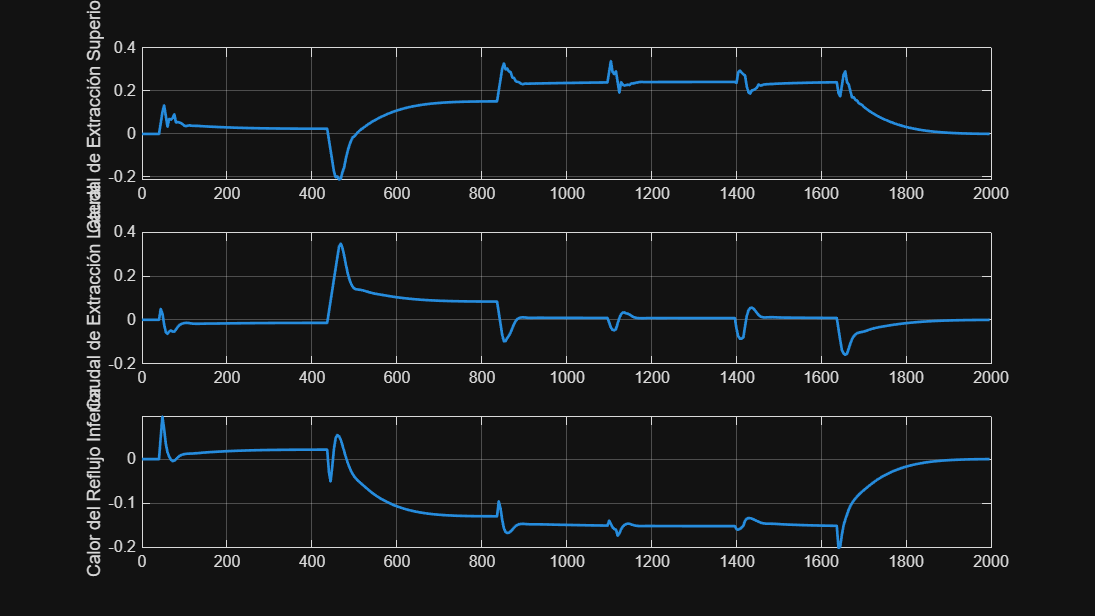

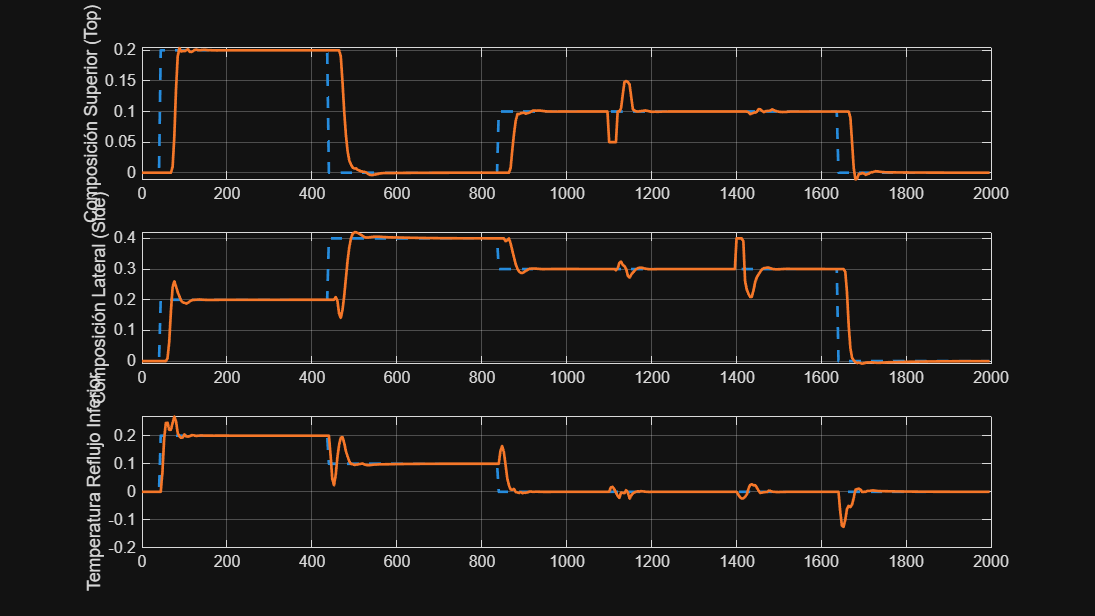


%% Graficar Resultados
for i = 1:my
    % Figura 20: Esfuerzo de Control (Válvulas / Actuadores)
    figure(20)
    set(gcf, 'Position', get(0, 'Screensize')); 
    subplot(3,1,i); plot(t, u(:,i), 'linewidth', 2); grid on; ylabel(ulab{i});
    set(gca, 'FontSize', 12);
    
    % Figura 21: Variables Controladas vs Referencias
    figure(21)
    set(gcf, 'Position', get(0, 'Screensize')); 
    subplot(3,1,i); plot(t, r(:,i), '--', t, y(:,i), 'linewidth', 2); grid on; ylabel(ylab{i});
    set(gca, 'FontSize', 12);
end